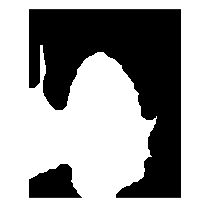

clear
% Read img file
img = imread("../db/DB0/db0_1.jpg");

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

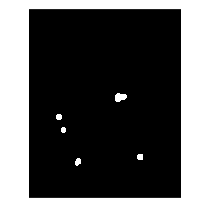


%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes,face_mask);
imshow(eye_mask)

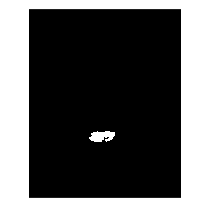



mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask);

[indexX,indexY] = eye_index(eye_mask);
mouth_center = [x, y]; % replace with actual coordinates
% [eye1 , eye2] = findEyePair(indexX,indexY,mouth_center);